EE3510 HW5 105060012張育菘

In this homework, you are going to design a PID controller to control the inverted pendulum model in homework 4. 

1) Use ode45 to simulate the output response in time-domain.

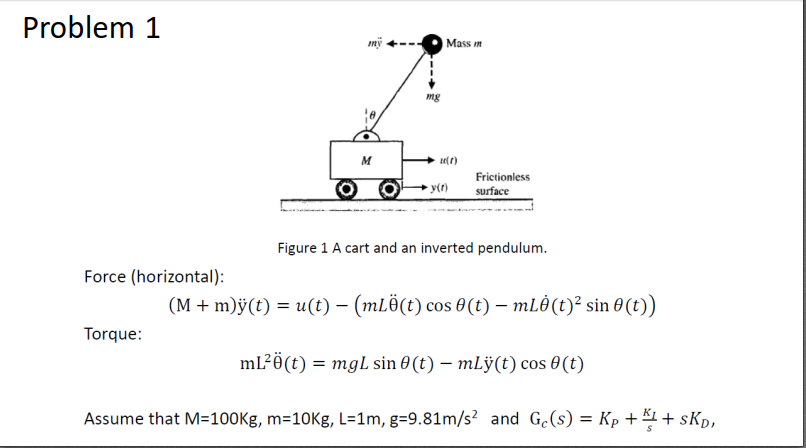

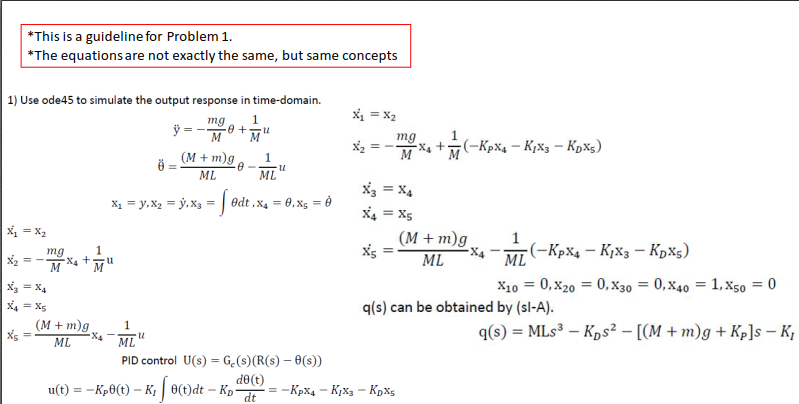


$$G\left(s\right)=\frac{-0\ldotp 01}{\left(s+3\ldotp 285\right)\left(s-3\ldotp 285\right)},\mathrm{PID}\left(s\right)=\frac{K_D s^2 +K_P s+K_I }{s}=\frac{K_{D\;} \left(s-z_1 \right)\left(s-z_2 \right)}{s}$$



$$q\left(s\right)={\mathrm{MLs}}^3 -K_D s^2 -\left\lbrack \left(M+m\right)g+K_P \right\rbrack s-K_I =0$$


$\Longrightarrow$For Stable system, $-K_D >0,-\left\lbrack \left(M+m\right)g+K_P \right\rbrack -\frac{K_I }{K_D }\mathrm{ML}>0,-K_I >0$

$\Longrightarrow$For Marginally Stable system, $K_D <0,K_I <0,K_P =-\left\lbrack \left(M+m\right)g\right\rbrack -\frac{K_I }{K_D }\textrm{ML}$

$\Longrightarrow$I design a stable system with $K_D =-50,K_I =-50,K_P =-1229\ldotp 1$

close all; clear;
fprintf("Q1 \n");

Q1 


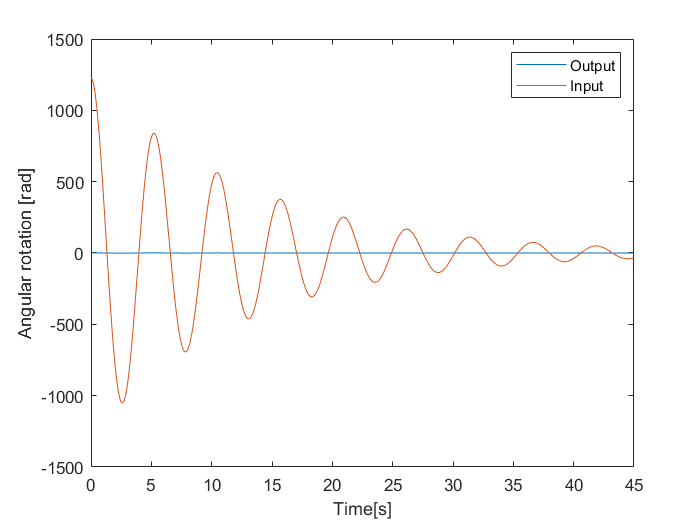


% Parameters
m = 10; M = 100; L = 1; g = 9.81;

% PID tuning
KD = -50; KI = -50; KP = -((M+m)*g)-((KI/KD)*M*L)-50;

% Reference signal
r = 0; c_in = [0;1/M;0;0;-1/(M*L)];
ref_sig=@(t, x)[x(2);-m*g*x(4)/M;x(4);x(5);(M+m)*g*x(4)/(M*L)]+(-KP*x(4)-KI*x(3)-KD*x(5))*c_in;
T = linspace(0, 45, 3*1e3);
x0 = [0; 0; 0; 1; 0];
[t, Y] = ode45(@(t, x) ref_sig(t, x), T, x0);

u = (-KP.*Y(:,4)) + (-KI.*Y(:,3)) + (-KD.*Y(:,5));

% Plot
figure; plot(t, Y(:,4), t, u);
xlabel('Time[s]');
ylabel('Angular rotation [rad]');
legend(["Output"], ["Input"]);

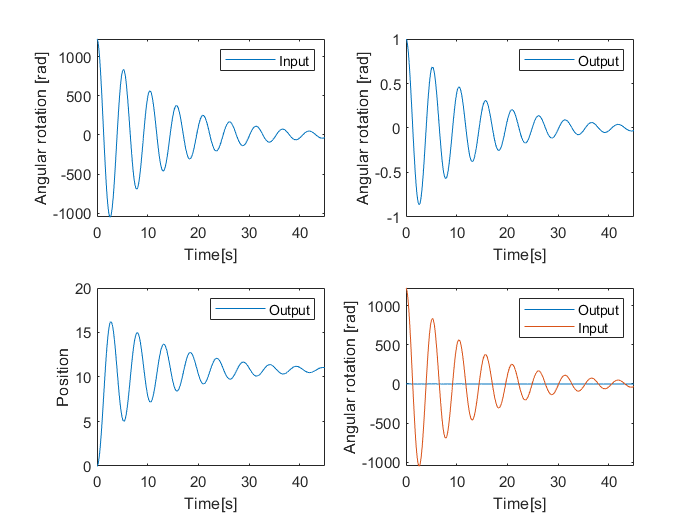


figure; 
subplot(2,2,1); plot(t, u);
xlabel('Time[s]'); ylabel('Angular rotation [rad]');
legend(["Input"]);
subplot(2,2,2); plot(t, Y(:,4));
xlabel('Time[s]'); ylabel('Angular rotation [rad]');
legend(["Output"]);
subplot(2,2,3); plot(t, Y(:,1));
xlabel('Time[s]'); ylabel('Position');
legend(["Output"]);
subplot(2,2,4); plot(t, Y(:,4), t, u);
xlabel('Time[s]'); ylabel('Angular rotation [rad]');
legend(["Output"], ["Input"]);


syms x;
eqn = M*L*x^3 - KD*x^2 - ((M+m)*g+KP)*x - KI == 0;
s = solve(eqn, x);
digits(6) % sets the precision used by vpa to 6 significant decimal digits.
vpa(s) % Variable-precision arithmetic

$$ans = \left(\begin{array}{c} -0.345627\\ -0.0771863-1.20029\,\mathrm{i}\\ -0.0771863+1.20029\,\mathrm{i} \end{array}\right)$$

由模擬結果顯示`，output 確實會漸漸 decay 至 0，這顯示此為一個穩定的系統。`

2) Use Simulink to simulate the output response in s-domain.

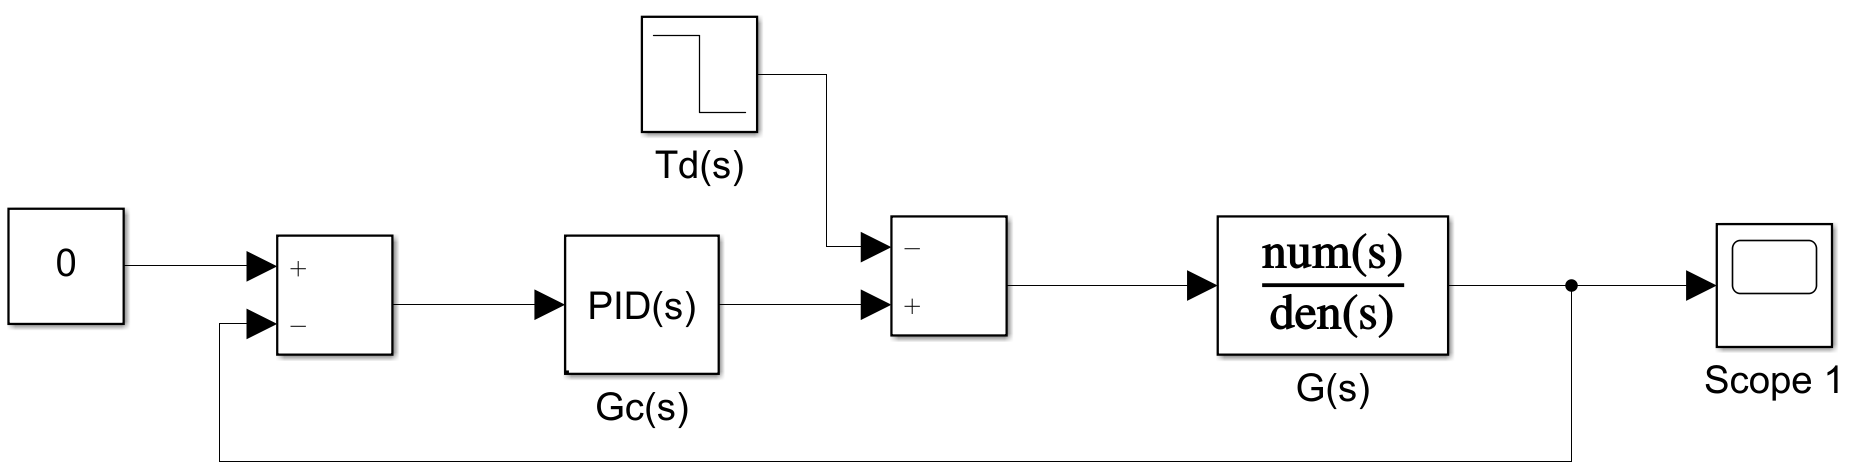

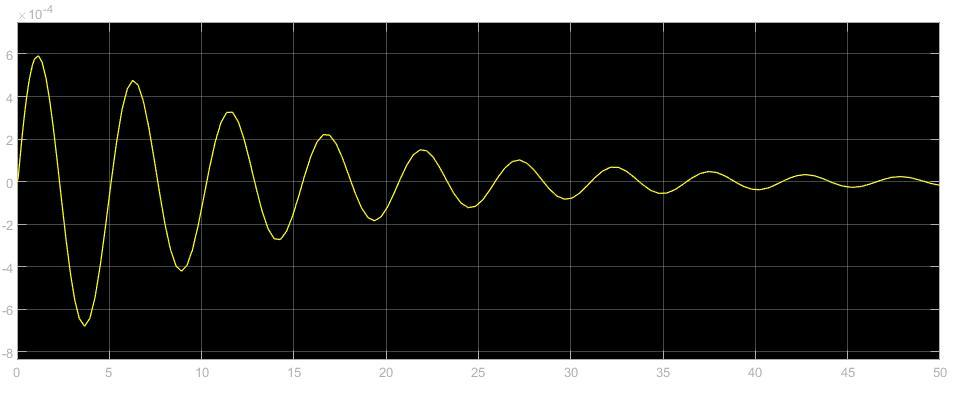

由 Simulink 模擬結果顯示`，此為一個穩定的系統。`

close all; clear;
fprintf("Q2 \n");

Q2 


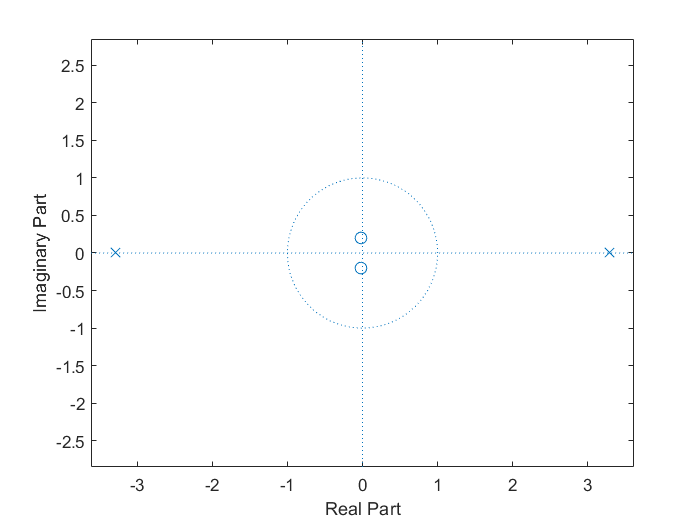


% Parameters
m = 10; M = 100; L = 1; g = 9.81;

% PID tuning
KD = -50; KI = -50; KP = -((M+m)*g)-((KI/KD)*M*L)-50;

b = [-1/(M*L)]; % -0.01
a = [1 0 -(M+m)*g/(M*L)]; % [1 0 -10.7910]

b_pid = [KP KI KD]; a_pid = [1];
b_all = conv(b_pid, b); a_all = conv(a_pid, a);
figure; zplane(b_all,a_all);


% open-loop system
fprintf("open-loop system \n");

open-loop system 


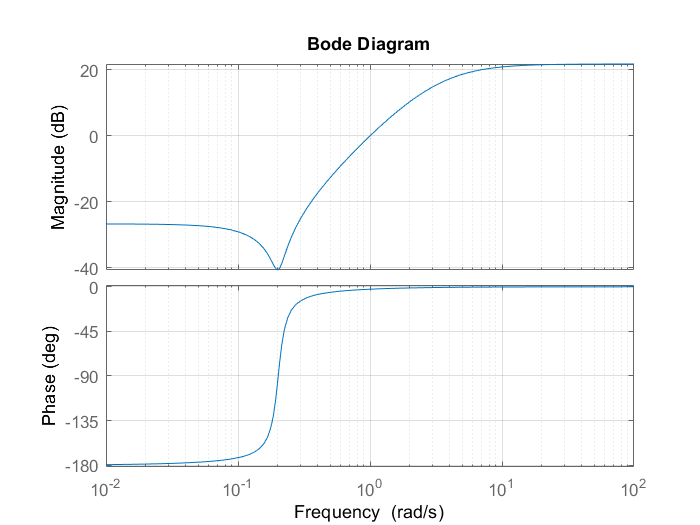

sys = tf(b_all, a_all);
figure; bode(sys); grid on;

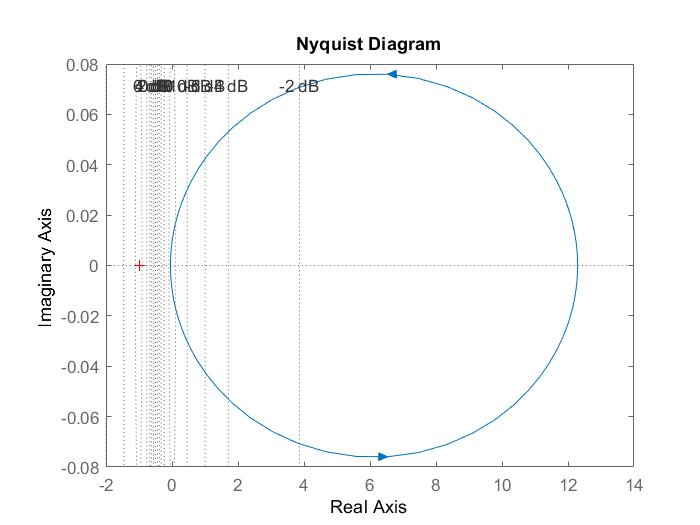

figure; nyquist(sys); grid on;


% closed-loop system
fprintf("closed-loop system \n");

closed-loop system 


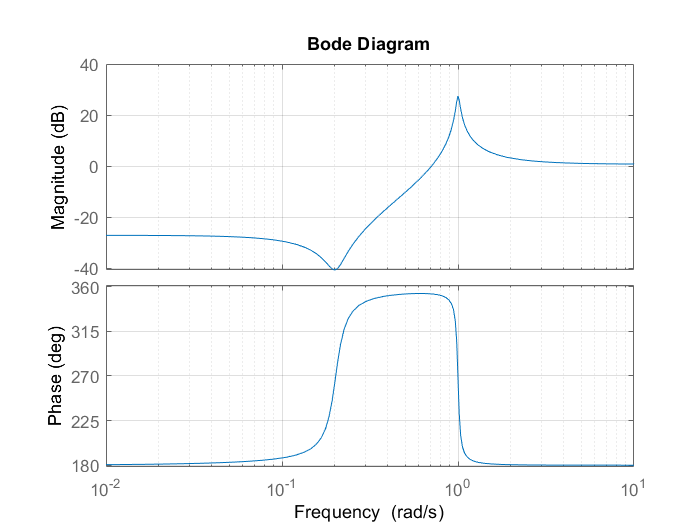

T_sys = feedback(sys,1,+1);
figure; bode(T_sys); grid on;

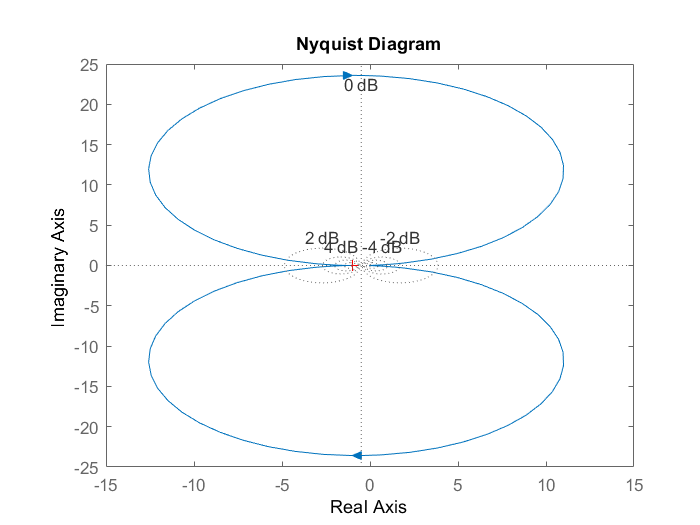

figure; nyquist(T_sys); grid on;